# Artificial Neural Network for Predictive Maintenance



clear
clc
close all

dataPath = "../data/datasets/ai4i2020.csv";

machineData = readtable(dataPath);

## Feature Selection



featureNames = [ ...
    "AirTemperature_K_", ...
    "ProcessTemperature_K_", ...
    "RotationalSpeed_rpm_", ...
    "Torque_Nm_", ...
    "ToolWear_min_"];

X = machineData(:,featureNames);

Y = machineData.MachineFailure;

## Convert Data



X = table2array(X);

Y = double(Y);

## Normalize Features



X = normalize(X);


## Train/Test Split



rng(42)

cv = cvpartition(Y,"HoldOut",0.30);

XTrain = X(training(cv),:);
XTest = X(test(cv),:);

YTrain = Y(training(cv));
YTest = Y(test(cv));

XTrain = XTrain';
XTest = XTest';

YTrain = YTrain';
YTest = YTest';

## Build Neural Network



net = patternnet(10);

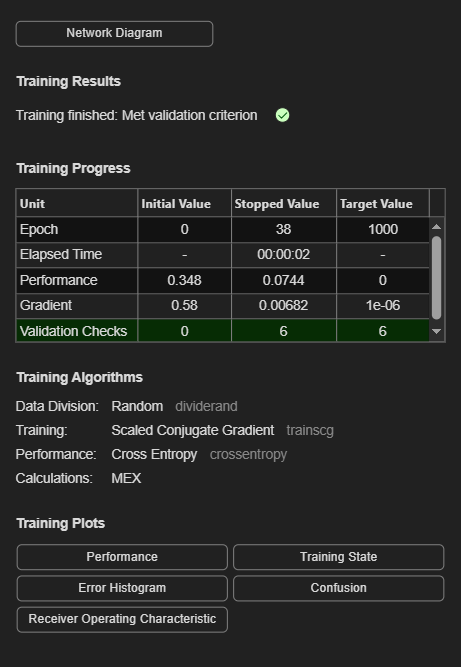

net = train(net,XTrain,YTrain);

YPred = net(XTest);

YPred = double(YPred > 0.5);

class(YTest)

ans = 'double'

class(YPred)

ans = 'double'

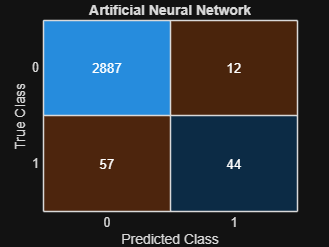

figure
confusionchart(YTest, YPred)
title("Artificial Neural Network")

%% Neural Network Performance Metrics

cm_NN = confusionmat(YTest, YPred);

TN = cm_NN(1,1);
FP = cm_NN(1,2);
FN = cm_NN(2,1);
TP = cm_NN(2,2);

accuracy = (TP + TN) / sum(cm_NN(:));
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1 = 2 * (precision * recall) / (precision + recall);

fprintf("\nNeural Network Results\n")


Neural Network Results


fprintf("--------------------------\n")

--------------------------


fprintf("Accuracy  : %.2f%%\n", accuracy*100)

Accuracy  : 97.70%


fprintf("Precision : %.2f%%\n", precision*100)

Precision : 78.57%


fprintf("Recall    : %.2f%%\n", recall*100)

Recall    : 43.56%


fprintf("F1 Score  : %.2f%%\n", f1*100)

F1 Score  : 56.05%
